# B. 5G DL-TDOA Integrity Analysis

Post-processing of A5_NR_Positioning.mlx: each epoch uses its own LoS gNB set and TDOA reference. The protection levels are conditional Gaussian-model bounds, not fault-certified integrity.

## Overview and configuration

%% 5G DL-TDOA Integrity Analysis
% Post-processes every positioning epoch saved by A5_NR_Positioning.mlx.
% G and R are formed from the base stations actually used at each epoch.
% HPL and VPL are CONDITIONAL, local Gaussian-model protection bounds.
% They are NOT certified integrity guarantees and do not cover unbounded NLOS.

clc; clear; close all;
addpath('./config');
run('config');

## 1. Load positioning outputs

%% 1. Load source data
% The original positioning script writes these MAT-files via config.m.
requiredFiles = {rxENUFile, nrLoSFile, nrSimFile, nrObsFile};
for j = 1:numel(requiredFiles)
    assert(isfile(requiredFiles{j}), ...
        'Missing simulation file: %s', char(requiredFiles{j}));
end

load(rxENUFile, 'receiverPositions', 'samplingRate');
load(nrLoSFile, 'LoSbStationsENU', 'LoSMatrix');
load(nrSimFile, 'epochEstim', 'epochError', 'Ts5g_pos');
load(nrObsFile, 'tdoaEstim', 'tdoaError');

% A5_NR_Positioning.mlx uses Fs5g_pos = samplingRate/2 and step = 2.
step = 2;
truthENU = double(receiverPositions(1:step:end-1, :));
los5G = LoSMatrix(1:step:end-1, :);
gNBpos = double(LoSbStationsENU);
originalPos = double(epochEstim);

nEpochs = size(tdoaEstim, 1);
nBS = size(gNBpos, 1);
assert(size(gNBpos,2)==3, 'gNB positions must be ENU [NBS x 3].');
assert(size(tdoaEstim,2)==nBS, 'TDOA columns must match gNB IDs.');
assert(size(los5G,2)==nBS, 'LoS columns must match gNB IDs.');
assert(size(originalPos,1)==nEpochs && size(originalPos,2)==3, ...
       'epochEstim must have dimensions [Nepochs x 3].');
assert(size(truthENU,1)>=nEpochs && size(los5G,1)>=nEpochs, ...
       'Not enough source trajectory/LoS epochs.');
assert(isscalar(Ts5g_pos) && Ts5g_pos>0, 'Invalid 5G epoch period.');
assert(abs(Ts5g_pos - step/samplingRate) < ...
       1e-9*max(1,abs(Ts5g_pos)), 'Sampling period disagrees with A5.');
truthENU = truthENU(1:nEpochs,:);
los5G = los5G(1:nEpochs,:);
tEpoch_s = (0:nEpochs-1).' * Ts5g_pos;

## 2. Configure the integrity model

%% 2. Integrity assumptions (REPLACE by calibrated values)
c = 299792458;
sigmaTOA_ns = 1.0;       % EXAMPLE: TOA random std [ns], not calibrated
syncBiasBound_ns = 0;   % EXAMPLE: absolute gNB clock-bias bound [ns]
nlosBiasBound_ns = 0;   % Only LoS stations are used in A5; no NLoS bound
HAL_m = NaN;            % Optional operational horizontal alert limit [m]
VAL_m = NaN;            % Optional operational vertical alert limit [m]

cfgBase = struct();
cfgBase.dim = 3;             % 3D position, or 2 if UP is externally fixed
cfgBase.pH = 5e-8;           % Horizontal conditional tail probability
cfgBase.pV = 5e-8;           % Two-sided vertical conditional tail probability
cfgBase.maxIter = 60;
cfgBase.tol_m = 1e-5;

% Assumption: common constant standard deviation of individual TOAs.
% The TDOA covariances are NOT independent because of shared reference.
sigmaTOA_s = sigmaTOA_ns * 1e-9;
absBiasBound_s = (syncBiasBound_ns + nlosBiasBound_ns)*1e-9;

## 3. Initialize integrity arrays

%% 3. Allocate per-epoch integrity and error outputs
HPL5G = nan(nEpochs,1);
VPL5G = nan(nEpochs,1);
HPLrandom5G = nan(nEpochs,1);
VPLrandom5G = nan(nEpochs,1);
HPLbias5G = nan(nEpochs,1);
VPLbias5G = nan(nEpochs,1);
errH5G = nan(nEpochs,1);
errV5G = nan(nEpochs,1);
errHoriginal5G = nan(nEpochs,1);
maxTDOAerror_m = nan(nEpochs,1);
P5G = nan(3,3,nEpochs);
positionWLS5G = nan(nEpochs,3);
valid5G = false(nEpochs,1);
refGNB = nan(nEpochs,1);
nUsedGNB = zeros(nEpochs,1);
G5G = cell(nEpochs,1);
R5G = cell(nEpochs,1);
residual5G = cell(nEpochs,1);
status5G = repmat({''},nEpochs,1);

## 4. Evaluate every 5G epoch

%% 4. Integrity evaluation at EVERY epoch
% A5 stores tdoaEstim(epoch,vBS(2:end)) = toa_i - toa_ref.
% The first LoS station vBS(1) is the reference; its entry is NaN.
% A pseudo-TOA vector [0; TDOAs] is sufficient because D*TOA is invariant
% to a common offset. Do not interpret these as absolute TOAs.

for epoch = 1:nEpochs
    vBS = find(los5G(epoch,:) == 1);
    nUsedGNB(epoch) = numel(vBS);

    if numel(vBS) < cfgBase.dim+1
        status5G{epoch} = 'Too few visible gNBs.';
        continue;
    end

    ref = vBS(1);
    others = vBS(2:end);
    stored = find(isfinite(tdoaEstim(epoch,:)));

    % Refuse to silently mix reference stations or measurement subsets.
    if ~isequal(stored(:), others(:))
        status5G{epoch} = 'Stored TDOA indices do not match LoS gNBs.';
        continue;
    end

    dt_s = double(tdoaEstim(epoch, others)).';
    pseudoTOA_s = [0; dt_s];
    gNBPosEpoch = gNBpos(vBS,:);
    cfg = cfgBase;
    cfg.biasBound_s = absBiasBound_s * ones(numel(vBS),1);

    % Original simulation estimate is a legitimate, non-truth initial guess.
    initialGuess = originalPos(epoch,:);
    if any(~isfinite(initialGuess)) || all(initialGuess==0)
        previous = find(valid5G(1:epoch-1),1,'last');
        if isempty(previous)
            status5G{epoch} = 'No usable initial position estimate.';
            continue;
        end
        initialGuess = positionWLS5G(previous,:);
    end

    % Optional strict consistency check against A5's stored observation
    % error: tdoaError = true TDOA - estimated TDOA.
    if exist('tdoaError','var') && ...
            all(isfinite(tdoaError(epoch,others)))
        trueRanges = vecnorm(gNBPosEpoch - truthENU(epoch,:),2,2);
        trueDt_s = (trueRanges(2:end)-trueRanges(1))/c;
        loggedDtError_s = double(tdoaError(epoch,others)).';
        mismatch_s = max(abs(trueDt_s - dt_s - loggedDtError_s));
        if mismatch_s > 1e-10
            status5G{epoch} = 'TDOA sign/order inconsistent with logged errors.';
            continue;
        end
        maxTDOAerror_m(epoch) = c*max(abs(loggedDtError_s));
    end

    result = tdoaIntegrity5G(pseudoTOA_s, gNBPosEpoch, ...
                             initialGuess, sigmaTOA_s, cfg);
    if ~result.valid
        status5G{epoch} = result.message;
        continue;
    end

    valid5G(epoch) = true;
    status5G{epoch} = result.message;
    refGNB(epoch) = ref;
    positionWLS5G(epoch,:) = result.xhat_ENU;
    HPL5G(epoch) = result.HPL_m;
    VPL5G(epoch) = result.VPL_m;
    HPLrandom5G(epoch) = result.HPL_random_m;
    VPLrandom5G(epoch) = result.VPL_random_m;
    HPLbias5G(epoch) = result.Hbias_m;
    VPLbias5G(epoch) = result.Vbias_m;
    P5G(:,:,epoch) = result.P_ENU_m2;
    G5G{epoch} = result.G;
    R5G{epoch} = result.R_m2;
    residual5G{epoch} = result.residual_m;

    errorENU = result.xhat_ENU - truthENU(epoch,:);
    errH5G(epoch) = hypot(errorENU(1),errorENU(2));
    errV5G(epoch) = abs(errorENU(3));
    originalError = originalPos(epoch,:) - truthENU(epoch,:);
    errHoriginal5G(epoch) = hypot(originalError(1),originalError(2));
end

## 5. Evaluate coverage and availability

%% 5. Model-bound exceedances and availability diagnostics
horizontalExceed = valid5G & (errH5G > HPL5G);
verticalExceed = valid5G & (errV5G > VPL5G);

nValid = nnz(valid5G);
fprintf('\n--- 5G DL-TDOA integrity summary ---\n');


--- 5G DL-TDOA integrity summary ---


fprintf('Positioning epochs: %d\n',nEpochs);

Positioning epochs: 183


fprintf('Valid 3D WLS/PL epochs: %d (%.1f%%)\n',nValid,100*nValid/nEpochs);

Valid 3D WLS/PL epochs: 179 (97.8%)


fprintf('Horizontal model-bound exceedances: %d\n',nnz(horizontalExceed));

Horizontal model-bound exceedances: 0


fprintf('Vertical model-bound exceedances: %d\n',nnz(verticalExceed));

Vertical model-bound exceedances: 0


fprintf('Epochs with <= 4 gNBs: %d (no redundancy if exactly 4)\n', ...
        nnz(nUsedGNB<=4));

Epochs with <= 4 gNBs: 20 (no redundancy if exactly 4)



if isfinite(HAL_m) && isfinite(VAL_m)
    available5G = valid5G & HPL5G<=HAL_m & VPL5G<=VAL_m;
    fprintf('Availability for supplied HAL/VAL: %.1f%% of all epochs\n', ...
            100*nnz(available5G)/nEpochs);
else
    available5G = false(nEpochs,1);
    fprintf('Operational availability not evaluated: set HAL_m and VAL_m.\n');
end

Operational availability not evaluated: set HAL_m and VAL_m.



fprintf(['IMPORTANT: these exceedance counts cannot validate a probability ' ...
         'as low as 5e-8 with only %d epochs.\n'],nEpochs);

IMPORTANT: these exceedance counts cannot validate a probability as low as 5e-8 with only 183 epochs.


fprintf('The PL is conditional on sigmaTOA_ns and the configured bias bounds.\n');

The PL is conditional on sigmaTOA_ns and the configured bias bounds.


## 6. Plot HPL/VPL and errors

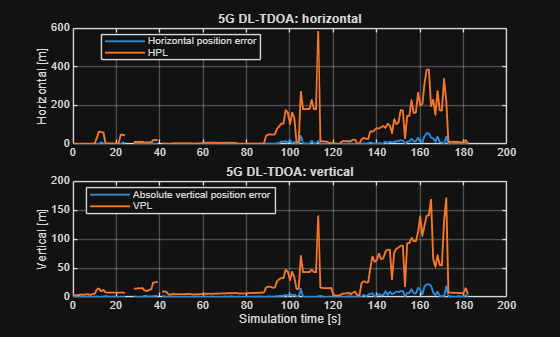

%% 6. Visualize horizontal and vertical protection
figure('Name','5G Integrity: protection vs. positioning error');
tiledlayout(2,1,'TileSpacing','compact');
nexttile;
plot(tEpoch_s,errH5G,'LineWidth',1.4); hold on;
plot(tEpoch_s,HPL5G,'LineWidth',1.4);
if isfinite(HAL_m), yline(HAL_m,'--','HAL'); end
hold off; grid on;
ylabel('Horizontal [m]'); title('5G DL-TDOA: horizontal');
legend('Horizontal position error','HPL','Location','best');
nexttile;
plot(tEpoch_s,errV5G,'LineWidth',1.4); hold on;
plot(tEpoch_s,VPL5G,'LineWidth',1.4);
if isfinite(VAL_m), yline(VAL_m,'--','VAL'); end
hold off; grid on;
ylabel('Vertical [m]'); xlabel('Simulation time [s]');
title('5G DL-TDOA: vertical');
legend('Absolute vertical position error','VPL','Location','best');

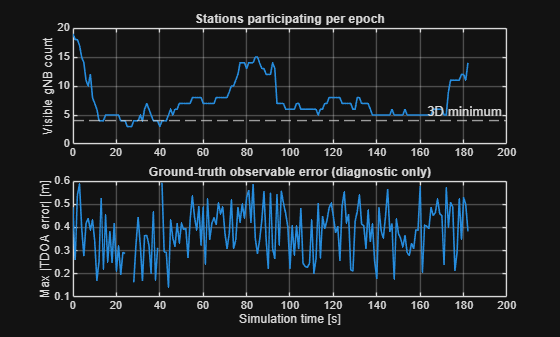


figure('Name','5G Integrity: geometry and TDOA observable errors');
tiledlayout(2,1,'TileSpacing','compact');
nexttile;
plot(tEpoch_s,nUsedGNB,'LineWidth',1.2); hold on;
yline(4,'--','3D minimum'); hold off; grid on;
ylabel('Visible gNB count');
title('Stations participating per epoch');
nexttile;
plot(tEpoch_s,maxTDOAerror_m,'LineWidth',1.2); grid on;
xlabel('Simulation time [s]'); ylabel('Max |TDOA error| [m]');
title('Ground-truth observable error (diagnostic only)');

## 7. Save results

%% 7. Save fully traceable results
integrity5G = struct();
integrity5G.tEpoch_s = tEpoch_s;
integrity5G.truthENU = truthENU;
integrity5G.originalPosENU = originalPos;
integrity5G.positionWLS_ENU = positionWLS5G;
integrity5G.valid = valid5G;
integrity5G.status = status5G;
integrity5G.referenceGNB = refGNB;
integrity5G.nUsedGNB = nUsedGNB;
integrity5G.HPL_m = HPL5G;
integrity5G.VPL_m = VPL5G;
integrity5G.HPL_random_m = HPLrandom5G;
integrity5G.VPL_random_m = VPLrandom5G;
integrity5G.HPL_bias_m = HPLbias5G;
integrity5G.VPL_bias_m = VPLbias5G;
integrity5G.errorHorizontal_m = errH5G;
integrity5G.errorVertical_m = errV5G;
integrity5G.errorHorizontalOriginal_m = errHoriginal5G;
integrity5G.maxTDOAerror_m = maxTDOAerror_m;
integrity5G.P_ENU_m2 = P5G;
integrity5G.G = G5G;
integrity5G.R_TDOA_m2 = R5G;
integrity5G.residual_m = residual5G;
integrity5G.horizontalExceedance = horizontalExceed;
integrity5G.verticalExceedance = verticalExceed;
integrity5G.operationalAvailable = available5G;
integrity5G.sigmaTOA_ns = sigmaTOA_ns;
integrity5G.syncBiasBound_ns = syncBiasBound_ns;
integrity5G.nlosBiasBound_ns = nlosBiasBound_ns;
integrity5G.pH = cfgBase.pH;
integrity5G.pV = cfgBase.pV;
integrity5G.HAL_m = HAL_m;
integrity5G.VAL_m = VAL_m;
integrity5G.note = ['Conditional Gaussian local PL. Assumed timing standard ' ...
    'deviation and bias bounds need independent calibration.'];

[outFolder,~,~] = fileparts(char(nrSimFile));
if isempty(outFolder), outFolder = '.'; end
integrityFile = fullfile(outFolder,'integrity5G_results.mat');
save(integrityFile,'integrity5G','-v7.3');
fprintf('Saved: %s\n',integrityFile);

Saved: .\data\estimations\integrity5G_results.mat


## 8. Local TDOA integrity functions

%% Local functions
% The implementation of tdoaIntegrity5G below uses a correlated TDOA R.
% It is embedded here so the Live Script is self-contained.
function out = tdoaIntegrity5G(toa_s, gNBPos_ENU, x0_ENU, sigmaTOA_s, cfg)
%TDOAINTEGRITY5G WLS position and Gaussian HPL/VPL for 5G DL-TDOA.
%
% Inputs (all transmitters must be in the same order):
%   toa_s         [M x 1] measured TOA, in seconds, with known PRS
%                 transmission scheduling offsets already removed.
%   gNBPos_ENU     [M x 3] gNB positions, in metres (E,N,U).
%   x0_ENU        [1 x 3] initial user position, in metres (E,N,U).
%   sigmaTOA_s    scalar or [M x 1] individual TOA standard deviations [s].
%   cfg           optional struct:
%     dim           3 (default) or 2 (fixed height x0_ENU(3)).
%     pH            horizontal tail risk, default 5e-8.
%     pV            vertical two-sided tail risk, default 5e-8.
%     biasBound_s   [M x 1] bound on |uncorrected TOA bias| in seconds;
%                   default zeros (NO protection from unmodelled faults).
%     Ctoa_s2       [M x M] full covariance of TOA errors in s^2;
%                   default diag(sigmaTOA_s.^2). If supplied, overrides it.
%     maxIter       maximum Gauss-Newton iterations (default 40).
%     tol_m         convergence threshold in metres (default 1e-6).
%
% Outputs: out.valid, out.message, out.xhat_ENU, out.G, out.R_m2,
%          out.P_ENU_m2, out.HPL_m, out.VPL_m, out.HPL_random_m,
%          out.VPL_random_m, out.Hbias_m, out.Vbias_m, out.residual_m.
%
% CAUTION: PLs are local Gaussian-model bounds, not certified integrity.
% Non-Gaussian NLOS, unmodelled clock biases, incorrect covariance and
% convergence to a wrong position can invalidate the bounds.

if nargin < 5 || isempty(cfg), cfg = struct(); end
if ~isfield(cfg,'dim'),         cfg.dim = 3; end
if ~isfield(cfg,'pH'),          cfg.pH = 5e-8; end
if ~isfield(cfg,'pV'),          cfg.pV = 5e-8; end
if ~isfield(cfg,'maxIter'),     cfg.maxIter = 40; end
if ~isfield(cfg,'tol_m'),       cfg.tol_m = 1e-6; end

c = 299792458;
toa = toa_s(:);
bs  = double(gNBPos_ENU);
x   = double(x0_ENU(:)).';
M   = numel(toa);
d   = cfg.dim;

out = struct('valid',false,'message','', 'xhat_ENU',nan(1,3), ...
    'G',[],'R_m2',[],'P_ENU_m2',nan(3), ...
    'HPL_m',nan,'VPL_m',nan, ...
    'HPL_random_m',nan,'VPL_random_m',nan, ...
    'Hbias_m',nan,'Vbias_m',nan,'residual_m',[], ...
    'iterations',0);

if ~ismember(d,[2 3]) || size(bs,1) ~= M || size(bs,2) ~= 3 ...
        || numel(x) ~= 3 || M < d+1
    out.message = 'Invalid dimensions or insufficient gNBs.';
    return;
end
if any(~isfinite([toa; bs(:); x(:)]))
    out.message = 'Non-finite TOA, position or gNB coordinates.';
    return;
end
if ~(cfg.pH>0 && cfg.pH<1 && cfg.pV>0 && cfg.pV<1)
    out.message = 'Tail probabilities must lie strictly between 0 and 1.';
    return;
end

if isscalar(sigmaTOA_s)
    sigma = repmat(double(sigmaTOA_s),M,1);
else
    sigma = double(sigmaTOA_s(:));
end
if numel(sigma) ~= M || any(~isfinite(sigma)) || any(sigma <= 0)
    out.message = 'Invalid TOA standard deviations.';
    return;
end

if isfield(cfg,'biasBound_s')
    b = double(cfg.biasBound_s(:));
else
    b = zeros(M,1);
end
if numel(b)~=M || any(~isfinite(b)) || any(b<0)
    out.message = 'Invalid absolute TOA bias bounds.';
    return;
end

if isfield(cfg,'Ctoa_s2') && ~isempty(cfg.Ctoa_s2)
    Ctoa = double(cfg.Ctoa_s2);
else
    Ctoa = diag(sigma.^2);
end
if ~isequal(size(Ctoa),[M M]) || any(~isfinite(Ctoa(:)))
    out.message = 'Invalid TOA covariance matrix.';
    return;
end
Ctoa = 0.5*(Ctoa+Ctoa.');

% First gNB is the reference: delta_tau_i1 = toa_i - toa_1.
D = [-ones(M-1,1), eye(M-1)];
z = c * (D * toa);                    % TDOA observations [m]
R = (c^2) * (D * Ctoa * D.');       % correlated TDOA covariance [m^2]
[L, cholFlag] = chol(R,'lower');
if cholFlag ~= 0
    out.message = 'TDOA covariance is not positive definite.';
    return;
end

converged = false;
for iter = 1:cfg.maxIter
    [h,G3,geometryOK] = modelTDOA(x,bs);
    if ~geometryOK
        out.message = 'User position coincides with a gNB.';
        return;
    end
    G = G3(:,1:d);
    A = L\G;
    singularVals = svd(A);
    if numel(singularVals)<d || singularVals(end) <= 1e-10*singularVals(1)
        out.message = 'Unobservable / ill-conditioned gNB geometry.';
        return;
    end
    residual = z-h;
    delta = A \ (L\residual);       % WLS Gauss-Newton correction [m]
    if norm(delta)<cfg.tol_m
        converged = true;
        break;
    end

    % Backtracking: avoid accepting a step that increases WLS cost.
    cost0 = norm(L\residual)^2;
    step = 1;
    accepted = false;
    for j = 1:20
        candidate = x;
        candidate(1:d) = x(1:d) + step*delta.';
        [h2,~,ok] = modelTDOA(candidate,bs);
        if ok && norm(L\(z-h2))^2 < cost0
            x = candidate;
            accepted = true;
            break;
        end
        step = step/2;
    end
    if ~accepted
        out.message = 'Gauss-Newton line search failed.';
        return;
    end
    if norm(step*delta) < cfg.tol_m
        converged = true;
        break;
    end
end
if ~converged
    out.message = 'WLS estimator did not converge.';
    return;
end

[h,G3,geometryOK] = modelTDOA(x,bs);
if ~geometryOK
    out.message = 'Invalid final geometry.';
    return;
end
G = G3(:,1:d);
A = L\G;
[Q,U] = qr(A,0);
singularVals = svd(A);
if singularVals(end) <= 1e-10*singularVals(1)
    out.message = 'Unobservable final geometry.';
    return;
end

% P = inv(G' * inv(R) * G), computed via a stable QR factorization.
Uinv = U\eye(d);
P = Uinv*Uinv.';

% K maps TDOA range errors [m] to estimated position errors [m].
K = U\(Q.'/L);
% A bounded TOA bias affects all TDOAs through D (not independent).
Ktoa = c*K*D;                       % position error [m] per TOA bias [s]

hBias = sum(vecnorm(Ktoa(1:2,:).*b.',2,1));
Cen = P(1:2,1:2);
maxEigenvalue = max(eig(0.5*(Cen+Cen.')));
hRandom = sqrt(-2*log(cfg.pH)) * sqrt(max(0,maxEigenvalue));

P3 = nan(3);
P3(1:d,1:d) = P;
if d==3
    vBias = sum(abs(Ktoa(3,:)).*b.');
    vRandom = sqrt(2)*erfcinv(cfg.pV)*sqrt(max(0,P(3,3)));
    vpl = vRandom + vBias;
else
    vBias = nan;
    vRandom = nan;
    vpl = nan;                      % Height is fixed, not estimated.
end

out.valid = true;
out.message = 'OK (conditional Gaussian PL, not fault-certified).';
out.xhat_ENU = x;
out.G = G;
out.R_m2 = R;
out.P_ENU_m2 = P3;
out.HPL_random_m = hRandom;
out.VPL_random_m = vRandom;
out.Hbias_m = hBias;
out.Vbias_m = vBias;
out.HPL_m = hRandom+hBias;
out.VPL_m = vpl;
out.residual_m = z-h;
out.iterations = iter;
end

function [h,G3,ok] = modelTDOA(x,bs)
% h_i = norm(x-s_i) - norm(x-s_1) [m].
    differences = x-bs;
    ranges = sqrt(sum(differences.^2,2));
    ok = all(ranges > 1e-6);
    if ~ok
        h = []; G3 = [];
        return;
    end
    directions = differences./ranges;
    h = ranges(2:end) - ranges(1);
    G3 = directions(2:end,:) - directions(1,:);
end